clear
clc
% defining general variables
V_ac = 210; %in ml, acetic acid
V_but = 340; %in ml, butanol
rho_ac = 1.05; %in g/ml
rho_but = 0.81; %in g/ml
M_ac = 60; % Molar mass
M_but = 74;
n_ac = (V_ac*rho_ac)/M_ac; % no. of moles
n_but = (V_but*rho_but)/M_but;
t = (0:10:80);

%For reactor 1:
T_r1 = [100, 100.2, 104, 113.5, 120.1, 123.4, 123.9, 124.2, 124.7];
V_naoh_r1 = [9.1, 8,7.4, 6.3, 5.0, 4.3, 2.2, 1.2, 0.5]; %in ml
n_acid_r1 = 1*V_naoh_r1/1000; %mol of acid in sample neutralised by 1N NaOH
V_sample = 2; %volume of sample in ml
conc_acid_r1 = n_acid_r1*1000/V_sample;
cum_sample = (2:2:18);
water_lost = [0,16.5,15,16,11.5,9.5,5,2.0,1.3] ;%
cum_water_rem_r1 = zeros(1,length(water_lost));
for i=2:9
    cum_water_rem_r1(i) = water_lost(i)+cum_water_rem_r1(i-1);
end
vol_in_r1 = 550-cum_sample-cum_water_rem_r1;
n_acid_reacted_r1 = (vol_in_r1.*conc_acid_r1)/1000;
X1 = (n_ac-n_acid_reacted_r1)/(n_ac)

X1 =     0.3215    0.4237    0.4840    0.5761    0.6728    0.7253    0.8616    0.9251    0.9690



V_W_naoh = [0,9,7.1,6.1,5.1,4.1,4.4,2.4,1.5];
V_W = 5 % ml

V_W = 5

acid_lost = (((1.*V_W_naoh)/V_W).*water_lost) % in millimoles

acid_lost =          0   29.7000   21.3000   19.5200   11.7300    7.7900    4.4000    0.9600    0.3900


total_acid_lost=sum(acid_lost)

total_acid_lost = 95.7900

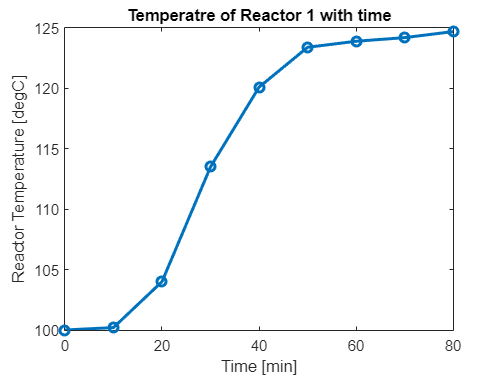


%For reactor 2:
T_r2 = [98.7, 97.4, 97, 96.9, 96.4, 96.5, 96.5, 96.6, 96.5];
V_naoh_r2 = [9.5, 8.5, 7.2, 6.2, 5.5, 5, 4.6, 4.4, 4.6];
n_acid_r2 = 1*V_naoh_r2/1000;
conc_acid_r2 = n_acid_r2*1000/V_sample;
V_in_r2 = 550-cum_sample;
n_acid_reacted_r2 = (V_in_r2.*conc_acid_r2)/1000;
X2 = (n_ac-n_acid_reacted_r2)/n_ac;

%Enhancement factor:
E = (X1-X2)./X2;

% error analysis


%Plots
plot(t, T_r1,'-o', 'LineWidth', 2)
title('Temperatre of Reactor 1 with time')
ylabel('Reactor Temperature [degC]')
xlabel('Time [min]')

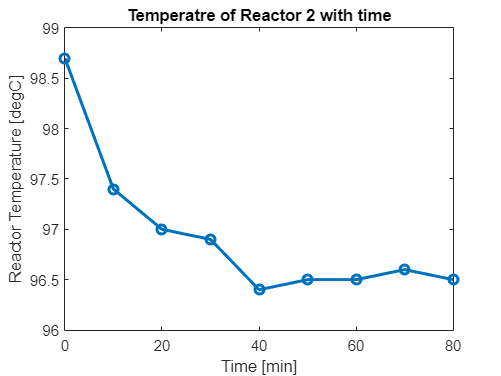


plot(t, T_r2, '-o','LineWidth', 2)
title('Temperatre of Reactor 2 with time')
ylabel('Reactor Temperature [degC]')
xlabel('Time [min]')

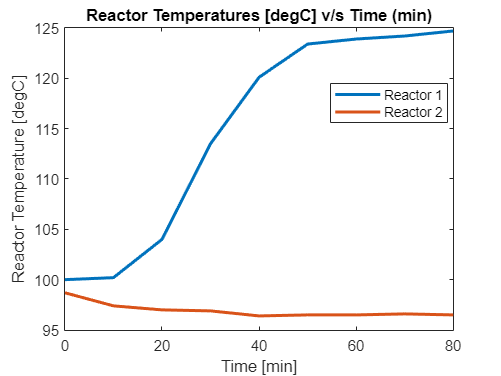


plot(t, T_r1, 'LineWidth', 2)
hold on
plot(t, T_r2, 'LineWidth', 2)
title('Reactor Temperatures [degC] v/s Time (min)')
ylabel('Reactor Temperature [degC]')
xlabel('Time [min]')
legend('Reactor 1', 'Reactor 2', 'Location','best')
hold off

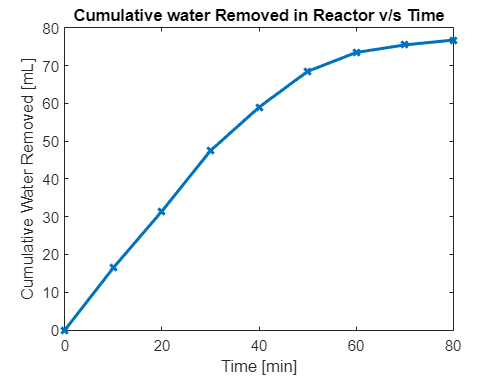


plot(t, cum_water_rem_r1, '-x','LineWidth',2)
xlabel('Time [min]')
ylabel('Cumulative Water Removed [mL]')
title('Cumulative water Removed in Reactor v/s Time')

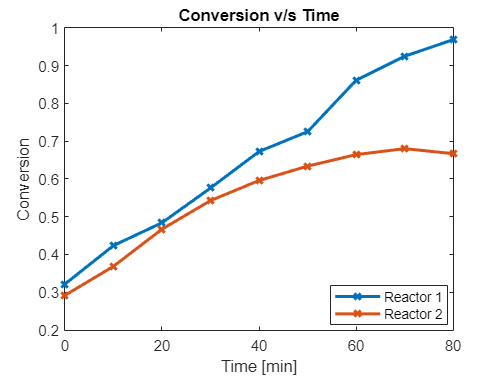



plot(t,X1,'-x','LineWidth',2)
hold on
plot(t,X2,'-x','LineWidth',2)
xlabel('Time [min]')
ylabel('Conversion')
title('Conversion v/s Time')
legend('Reactor 1', 'Reactor 2', 'Location','best')
%ylim([0 1])
hold off

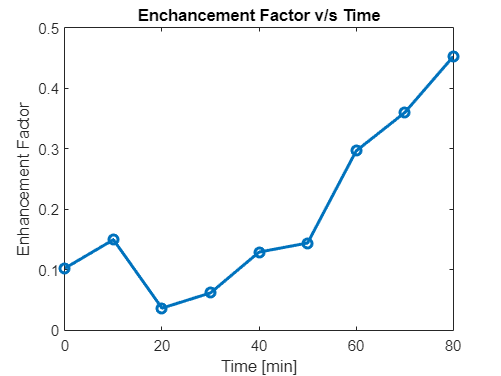


plot(t, E,'-o','LineWidth',2)
hold on
xlabel('Time [min]')
ylabel('Enhancement Factor')
title('Enchancement Factor v/s Time')
hold off




% for Reactor 1


Writing to Excel

filename='MT_302.xlsx';
T=table(t',T_r1',water_lost',V_naoh_r1',vol_in_r1',X1');
T.Properties.VariableNames = {'Time','Temperature','Water Lost','NaOH required','Volume remaining','Conversion (X1)'}

T = 9×6 table
    Time    Temperature    Water Lost    NaOH required    Volume remaining    Conversion (X1)
    ____    ___________    __________    _____________    ________________    _______________

      0          100             0            9.1                548              0.32152    
     10        100.2          16.5              8              529.5              0.42367    
     20          104            15            7.4              512.5              0.48401    
     30        113.5            16            6.3              494.5              0.57614    
     40        120.1          11.5              5                481              0.67279    
     50        123.4           9.5            4.3              469.5              0.72533    
     60        123.9         


writetable(T,filename,'Sheet','reactor 1')

T1=table(t',T_r2',V_naoh_r2',X2');
T1.Properties.VariableNames = {'Time','Temperature','NaOH required','Conversion (X2)'}

T1 = 9×4 table
    Time    Temperature    NaOH required    Conversion (X2)
    ____    ___________    _____________    _______________

      0        98.7             9.5              0.2917    
     10        97.4             8.5             0.36857    
     20          97             7.2              0.4671    
     30        96.9             6.2              0.5428    
     40        96.4             5.5             0.59592    
     50        96.5               5             0.63401    
     60        96.5             4.6             0.66454    
     70        96.6             4.4             0.68033    
     80        96.5             4.6             0.66705    



writetable(T1,filename,'Sheet','reactor 2')

results = table(t',X1',X2',E');
results.Properties.VariableNames={'Time','Conversion (X1)', 'Conversion (X2)', 'Enhancement Factor'}

results = 9×4 table
    Time    Conversion (X1)    Conversion (X2)    Enhancement Factor
    ____    _______________    _______________    __________________

      0         0.32152             0.2917              0.10224     
     10         0.42367            0.36857               0.1495     
     20         0.48401             0.4671             0.036205     
     30         0.57614             0.5428             0.061422     
     40         0.67279            0.59592                0.129     
     50         0.72533            0.63401              0.14402     
     60         0.86156            0.66454              0.29647     
     70         0.92514            0.68033              0.35985     
     80         0.96903            0.66705              0.45272     


writetable(results,filename,'sheet','Results')
